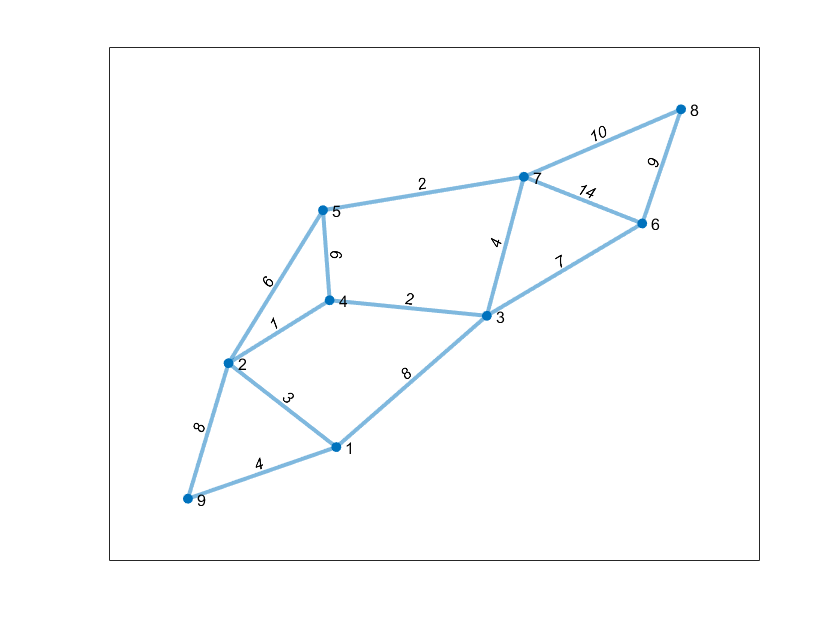

% 定义图的边和权重
s = [9 9 1 1 3 3 3 2 2 5 5 7 7 8];
t = [1 2 2 3 4 6 7 4 5 4 7 6 8 6];
w = [4 8 3 8 2 7 4 1 6 6 2 14 10 9];

G = graph(s,t,w);

plot(G, 'EdgeLabel', G.Edges.Weight, 'LineWidth', 2)

set(gca, 'XTick', [], 'YTick', []);


[P,d] = shortestpath(G, 9, 8)

P =      9     1     2     4     3     7     8


d = 24

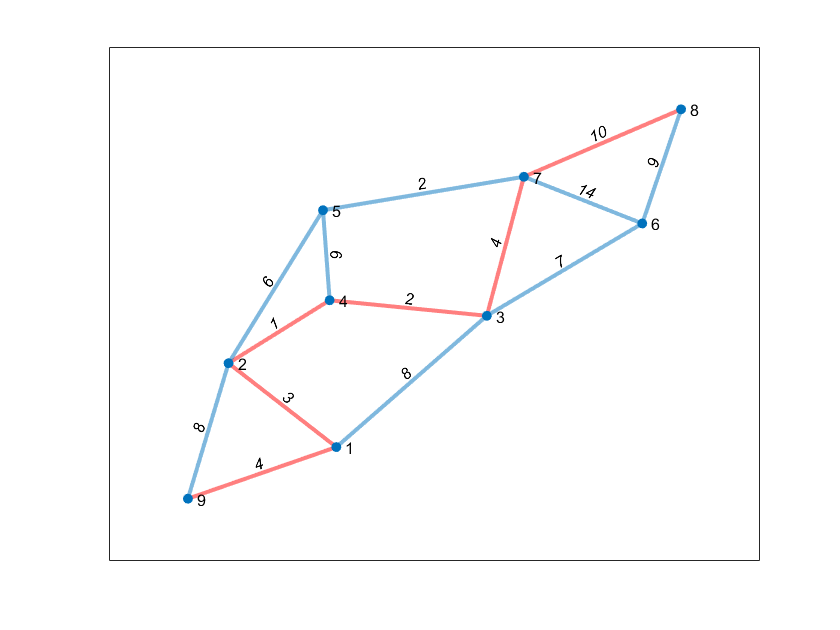

myplot = plot(G, 'EdgeLabel', G.Edges.Weight, 'LineWidth', 2);
highlight(myplot, P, 'EdgeColor', 'r')

% 计算图形G中任意两点之间的最短路径矩阵
D = distances(G)

D =      0     3     6     4     9    13    10    20     4
     3     0     3     1     6    10     7    17     7
     6     3     0     2     6     7     4    14    10
     4     1     2     0     6     9     6    16     8
     9     6     6     6     0    13     2    12    13
    13    10     7     9    13     0    11     9    17
    10     7     4     6     2    11     0    10    14
    20    17    14    16    12     9    10     0    24
     4     7    10     8    13    17    14    24     0


% 输出 1到 2的最短路径
D(1, 2)

ans = 3

% 输出 9到 4的最短路径
D(9, 4)

ans = 8

% 找出图形 G中距离节点 2不超过 10的所有节点
[nodeIDs, distances] = nearest(G, 2, 10)

nodeIDs =      4
     1
     3
     5
     7
     9
     6


distances =      1
     3
     3
     6
     7
     7
    10
